# Método de Euler explícito y modificado

Sol =          0    3.0000
    0.1000    3.3400
    0.2000    3.6185
    0.3000    3.8435
    0.4000    4.0221
    0.5000    4.1603
    0.6000    4.2635
    0.7000    4.3366
    0.8000    4.3836
    0.9000    4.4082


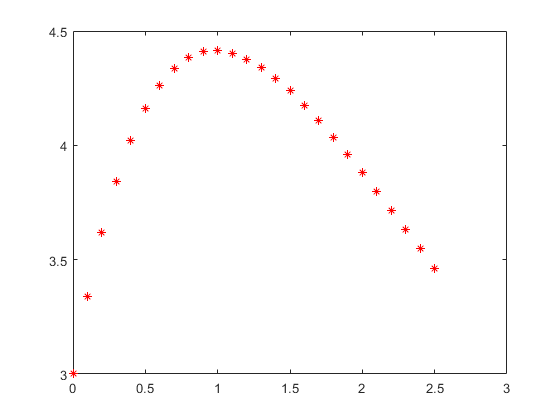

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000


y =     3.0000    3.3400    3.6185    3.8435    4.0221    4.1603    4.2635    4.3366    4.3836    4.4082    4.4136    4.4025    4.3775    4.3406    4.2936    4.2383    4.1761    4.1081    4.0355    3.9591    3.8799    3.7985    3.7155    3.6314    3.5468    3.4619


clear
a=0;b=2.5;h=0.1;y0=3;
f=@(x,y) -1.2*y+7*exp(-0.3*x);  %función
% Solución numérica Euler (x,y)
[x,y]=odeEuler(f,a,b,h,y0)

Sol =          0    3.0000
    0.1000    3.3093
    0.2000    3.5645
    0.3000    3.7724
    0.4000    3.9387
    0.5000    4.0689
    0.6000    4.1673
    0.7000    4.2382
    0.8000    4.2851
    0.9000    4.3112


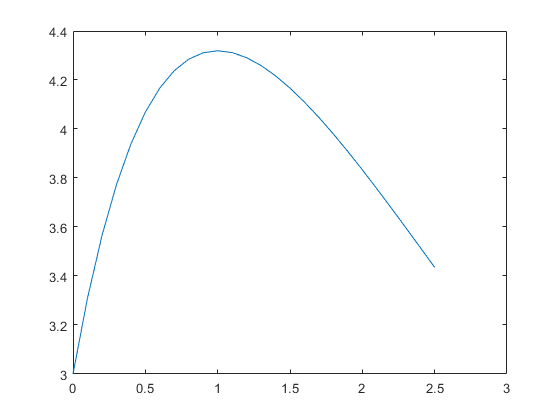

xm =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000


ym =     3.0000    3.3093    3.5645    3.7724    3.9387    4.0689    4.1673    4.2382    4.2851    4.3112    4.3193    4.3119    4.2911    4.2590    4.2170    4.1669    4.1098    4.0470    3.9794    3.9080    3.8334    3.7564    3.6777    3.5976    3.5166    3.4352


% Solución numérica Euler modificado (xm,ym)
[xm,ym]=odeModEuler(f,a,b,h,y0) 

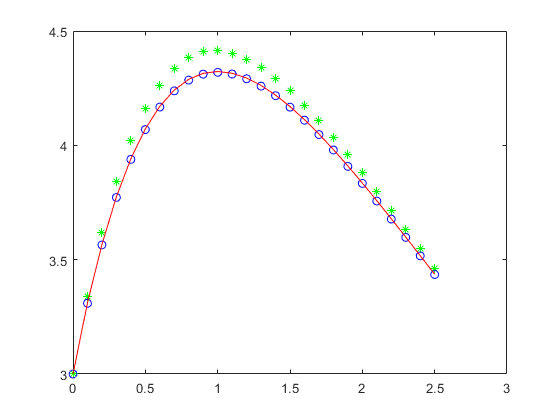

% Construcción de la solución verdadera (xv,yv)
xv=a:0.1:b;
yv=70/9*exp(-0.3*xv)-43/9*exp(-1.2*xv);
% Gráficas: Comparación resultados
%   verde: solución numérica Euler
%   azul: Solución numérica Euler Modificado
%   rojo: solución verdadera
plot(x,y,'*g',xm,ym,'o b',xv,yv,'red')